clear all
close all
sigmax=spinOp(5/2,'x');
sigmay=spinOp(5/2,'y');
sigmaz=spinOp(5/2,'z');

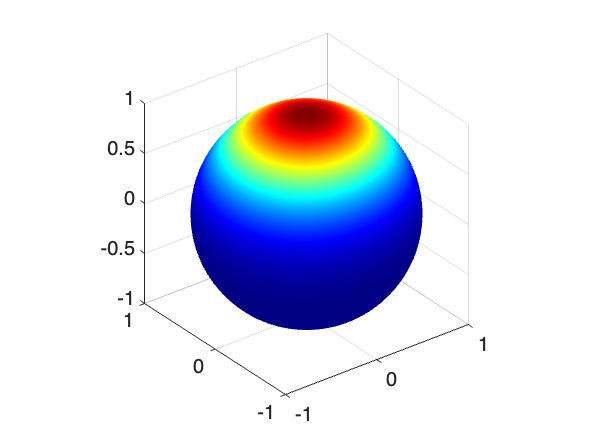

state1=[1 0 0 0 0 0]';
state_final=ham_evolve(sigmax^2,state1,pi*0.01);
Qfunction(state_final);
view(gca,[-37.5 30]);

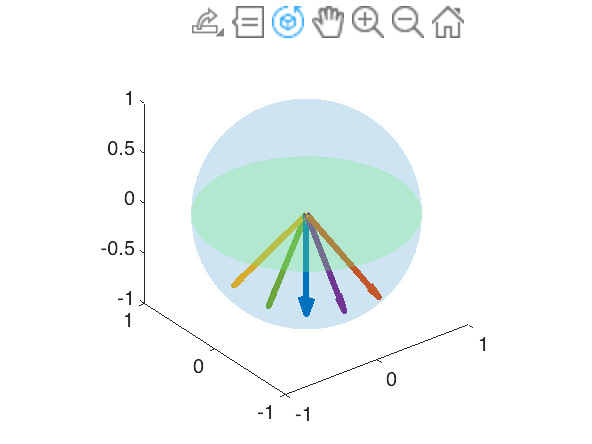


figure;
hold on
theta_list=[0:pi/50:pi];
phi_list=[0:2*pi/50:2*pi];
theta_list=pi/2-theta_list;
[theta2,phi2]=meshgrid(theta_list,phi_list);
[x,y,z]=sph2cart(phi2,theta2,1);
surf=mesh(x,y,z,'FaceLighting','none','EdgeLighting','flat',...
    'FaceAlpha',0.1,...
    'FaceColor',[0 0.447058823529412 0.741176470588235],...
    'EdgeAlpha',0);
colormap jet
r_list=[0:0.1:1];
[r2,phi2]=meshgrid(r_list,phi_list);
[x,y,z]=sph2cart(phi2,0,r2);
surf=mesh(x,y,z,'EdgeLighting','flat',...
    'FaceAlpha',0.3,...
    'FaceColor',[0 0.447058823529412 0.741176470588235],...
    'EdgeColor','none');
surf.FaceColor="flat";

[theta,phi]=findMS(state_final);
[x,y,z]=sph2cart(phi,pi/2-theta,1);
daspect([1 1 1]);
for i=1:5
    l=quiver3(0,0,0,x(i),y(i),z(i));
    l.LineWidth=3;
    l.MaxHeadSize=0.5;
    l.AutoScale="off";
end
view(gca,[-37.5 30]);

function [theta,phi]=findMS(state) % find majorana stars for the state
    poly_coeff=zeros(6,1);
    for i=1:6
        m=7/2-i;
        poly_coeff(i)=(-1)^(5/2+m)*sqrt(nchoosek(5,5/2+m))*state(i);
    end
    root=roots(poly_coeff);
    theta=acot(abs(root))*2; % 0 to pi 
    phi=angle(root); % -pi to pi

end
function f1=Qfunction(state)
    f1=figure;
    m=100;n=100;
    theta_list=[0:pi/(m-1):pi];
    phi_list=[0:2*pi/(n-1):2*pi];
    for i=1:length(theta_list)
        theta=theta_list(i);
        for j=1:length(phi_list)
            phi=phi_list(j);
            Qfunction_result(i,j)=scalar_product(state,spin_coherent(theta,phi));
        end
    end
    theta_list=pi/2-theta_list;
    [theta2,phi2]=meshgrid(theta_list,phi_list);
    [x,y,z]=sph2cart(phi2,theta2,1);
    surf=mesh(x,y,z,Qfunction_result');
    set(surf,'FaceLighting','none',...
    'EdgeLighting','flat',...
    'FaceColor','interp',...
    'EdgeColor','interp');
    xlim([-1 1]);
    zlim([-1 1]);
    ylim([-1 1]);
    daspect([1 1 1]);
    colormap jet
end
function state=spin_coherent(theta,phi)
sigmay=spinOp(5/2,'y');
sigmaz=spinOp(5/2,'z');
polar=[1 0 0 0 0 0]';
state1=ham_evolve(sigmay,polar,theta);
state=ham_evolve(sigmaz,state1,phi);
end
function final=ham_evolve(ham,initial,time)
try
    final=expm(-1i*ham*time)*initial;
catch 
    disp("Wrong Solution!!");
end
end
function result=scalar_product(state1,state2)
    result=abs(ctranspose(state1)*state2).^2;
end